clear

syms t; % tempo
syms T; % energia cinetica del sistema
syms U; % energia potenziale del sistema
syms alpha; % Angolo di offset statico che sposta in avanti il baricentro
syms beta; % Altro angolo statico, vedi disegno
syms l_c l_a l_b m_a m_c m_r m_b J_r J_b J_a J_c g r;
syms b; % Attrito viscoso
% Coordinate libere
syms phi(t); % posizione carrello
vel = diff(phi, t); %velocità carello
syms theta(t); % angolo inclinazione
vel_ang = diff(theta, t);%vel angolare
syms q_1 q_1_p q_2 q_2_p;

Definisco il problema per il punto Pa

P_a = [phi/r+l_a*sin(theta+beta);l_a*cos(theta+beta);theta]
V_a = diff(P_a,t);
M_a = [m_a,0,0;0,m_a,0;0,0,J_a];
T_a = 1/2 * transpose(V_a) * M_a * V_a;
U_a = m_a * g * l_a*cos(theta+beta);
L_a = T_a - U_a;


Definisco il problema per il punto Pc

P_c = [phi/r+l_c*sin(theta+alpha);l_c*cos(theta+alpha);alpha+theta]
V_c = diff(P_c,t);
M_c = [m_c,0,0;0,m_c,0;0,0,J_c];
T_c = 1/2 * transpose(V_c) * M_c * V_c;
U_c = m_c * g * l_c*cos(alpha+theta);
L_c = T_c - U_c;

Definisco il problema per il punto Pb

P_b = [phi/r+l_b*sin(theta);l_b*cos(theta);theta]
V_b = diff(P_b,t);
M_b = [m_b,0,0;0,m_b,0;0,0,J_b];
T_b = 1/2 * transpose(V_b) * M_b * V_b;
U_b = m_b * g * l_b*cos(theta);
L_b = T_b - U_b;

Definisco il problema per il punto Pr

P_r = [phi/r;0;theta]
V_r = diff(P_r,t);
M_r = [m_r,0,0;0,m_r,0;0,0,J_r];
T_r = 1/2 * transpose(V_r) * M_r * V_r;
U_r = 0;
L_r = T_r - U_r;

Eulero Lagrange wrt theta

syms q_1 q_1_p q_2 q_2_p;
L = collect(simplify(2*L_r + L_a + L_b +L_c))
L_q = subs(L,{phi,vel,theta,vel_ang},{q_1 q_1_p q_2 q_2_p});
dL_dq2p = diff(L_q,q_2_p);
dL_dq2 = diff(L_q,q_2);
dL_dvel_ang = subs(dL_dq2p,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});
dL_dtheta = subs(dL_dq2,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});
dL_dvel_ang_dt = diff(dL_dvel_ang,t);
% risultato = collect(dL_dvel_ang_dt - dL_dtheta + (b * vel_ang)) attrito
E_L_theta = collect(dL_dvel_ang_dt - dL_dtheta==0)

eulero lagrange wrt phi

dL_dq1p = diff(L_q,q_1_p);
dL_dq1 = diff(L_q,q_1);
dL_dvel = subs(dL_dq1p,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});
dL_dphi = subs(dL_dq1,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});
dL_dvel_dt = diff(dL_dvel,t);
%%attenzione, ci andrebbe una forza f dall'altro lato!
syms F;
E_L_phi = collect(dL_dvel_dt - dL_dphi==F)

Risolviamo le equazioni

acc_ang = diff(theta,t,2);
acc = diff(phi,t,2);
syms q1_s q2_s;
eqns = [subs(E_L_theta, {acc,acc_ang},{q1_s,q2_s}),subs(E_L_phi, {acc,acc_ang},{q1_s,q2_s})];
[teta2,phi2] = solve(eqns, [q1_s q2_s])

%temp_teta = solve(subs(E_L_theta,acc_ang,q2_s),q2_s);
%temp_phi = solve(subs(E_L_phi,acc,q1_s),q1_s);
%subs(E_L_phi,{acc,acc_ang},{q1_s,q2_s});



linearizzazione intorno all'equilibrio [0,0,0,0], uso la matrice A come in e-05 dynamics

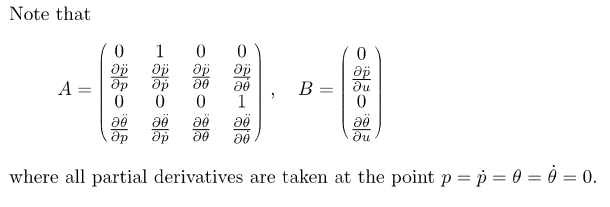


syms u;
teta2_differenziabile = subs(teta2,{phi,vel,theta,vel_ang,F},{q_1 q_1_p q_2 q_2_p u});
phi2_differenziabile = subs(phi2,{phi,vel,theta,vel_ang,F},{q_1 q_1_p q_2 q_2_p u});
%phi,phi_primo,theta,theta_primo,F
equilibrio = {0,0,0,0,0}

equilibrio = 1×5 cell array
    {[0]}    {[0]}    {[0]}    {[0]}    {[0]}


A11 = 0;
A12 = 1;
A13 = 0;
A14 = 0;
A21 = subs(diff(phi2_differenziabile,q_1),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A22 = subs(diff(phi2_differenziabile,q_1_p),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A23 = subs(diff(phi2_differenziabile,q_2),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A24 = subs(diff(phi2_differenziabile,q_2_p),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A31 = 0;
A32 = 0;
A33 = 0;
A34 = 1;
A41 = subs(diff(teta2_differenziabile,q_1),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A42 = subs(diff(teta2_differenziabile,q_1_p),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A43 = subs(diff(teta2_differenziabile,q_2),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A44 = subs(diff(teta2_differenziabile,q_2_p),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A = [A11 A12 A13 A14;A21 A22 A23 A24;A31 A32 A33 A34; A41 A42 A43 A44]

B11 = 0;
B21 = subs(diff(phi2_differenziabile,u),{q_1 q_1_p q_2 q_2_p u},equilibrio);
B31 = 0;
B41 = subs(diff(teta2_differenziabile,u),{q_1 q_1_p q_2 q_2_p u},equilibrio);
B = [B11;B21;B31;B41];
%volgio come uscita l'angolo
C = [0,0,1,0]

C =      0     0     1     0


D = 0;
syms s G(s);
G = C*(s*eye(4)-A)^-1*B+D